# Create Controller Using Simulink Blocks and Simulate

The initial model is using Simulink to handle the system's fault logic.  

This model will use ad-hoc testing and the Simulink **Dashboard** blocks to verify the behavior of the fault logic.ping electrification applications.

### The main topics to cover for this exercise are:

- Adding an If block to select the action;

- Configuring the If block;

- Testing the model using **Dashboard** blocks;

  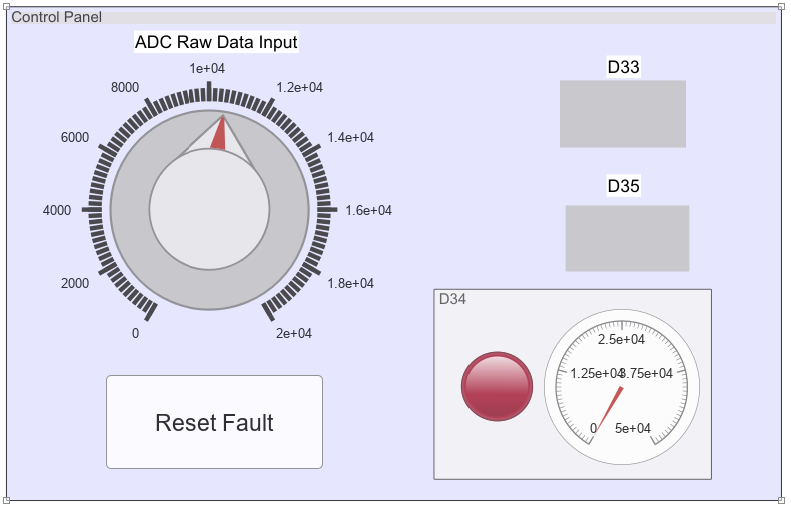                           

open_system('Exercise1_Start');

The opened model, includes part of the** FaultLogic** subsystem that will be used in future exercises, along with other necessary instructions. The model already has been configured to run the **Dashboard** blocks to control the model, and Simulation Pacing to slow down the simulation to be close to real time.  You will be adding an **If** block to the **FaultLogic** subsystem.

### Requirements for the next exercise:

- Add an **If** block in the specified location within the **FaultLogic** subsystem

- Configure the **If** block as specified within the **FaultLogic** subsystem

- Simulate the model, using the **Control Panel** to perform ad-hoc testing.

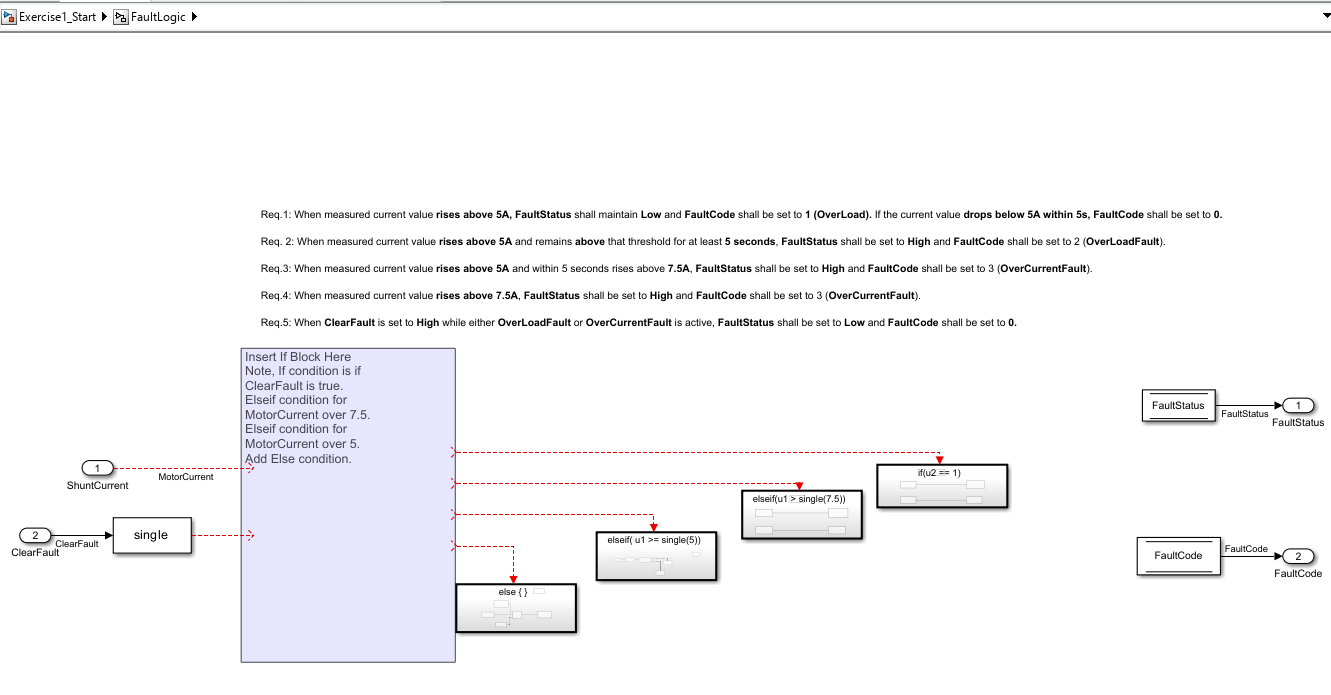

## Add the If block

The **If** block will be found in the Simulink Library Browser in the **Simulink -> Ports & Subsystems** library

- Go to **SIMULATION** tab and click on **Library Browser**.

- Double-click on the **FaultLogic** block to open that subsystem

- Drag & Drop the **If** block from **Simulink -> Ports & Subsystems **Library into our Simulink model, indicated by the blue area.

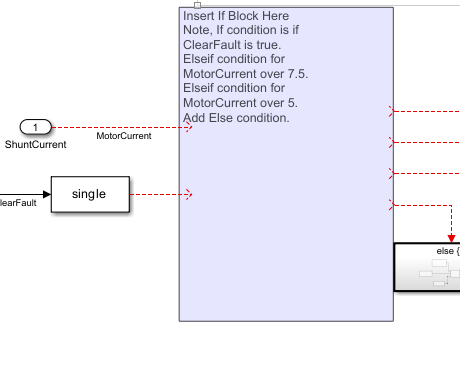

- Double-click on the **If** block to configure the block as needed.  The conditions are noted in the blue shaded region.  The block will require two input ports, one for the Motor Current, and one for the Clear Fault switch.

- *Hint:  *MotorCurrent will be specified in the **If** block as "u1," and ClearFault will be specified as "u2."  

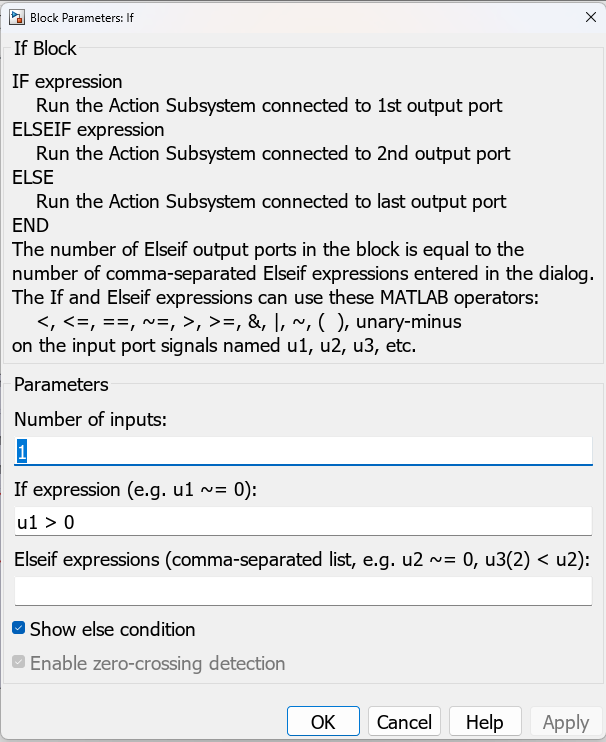

- Connect the inputs and the outputs to the appropriate signals and action subsystems.

## Test The Algorithm

At this point, we can use the dashboard blocks to test the algorithm.

For this ad-hoc testing:

- Return to top level of model

- Click on the **Run** button.

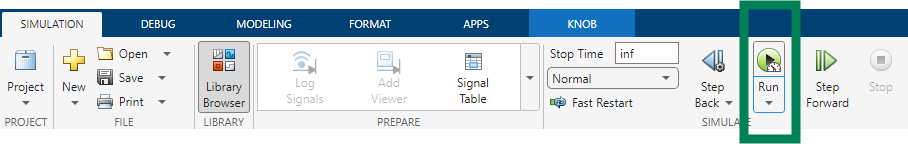

After the model starts running, attempt to create all the fault scenarios using the Control Panel.

- Normal operation:  current is below 5, no LEDs are lit

- Temporary overload:  current is between 5 and 7.5, D34 LED is lit, but current drops back below 5 before 5 seconds elapse.  D34 LED turns off when current drops below 5.

- Overload:  current is between 5 and 7.5 for more than 5 seconds, D33 LED is lit.  Decreasing current below 5 still keeps D33 LED lit until Reset Fault button is pressed.

- Reset Fault:  D33 LED turns off

- OverCurrent:  current is greater than 7.5.  D35 LED turns on.  Decreasing current below 5 still keeps D35 LED lit until Reset Fault button is pressed.

Upon completion of the exercise, stop the model.

Solution can be found here:

open_system('Exercise1_Solution');